clear all
close all
T = readtable("C:\Users\fmarini\Downloads\MATLAB Copilot Beta Survey(1-22).xlsx");

% Assume T is your table
% Extract data from columns 10 to 23
idx = 10:23;
data_plot = T{:, idx};
titles = T.Properties.VariableNames(idx);

titles = {'Ask Copilot';
    'Autocompletions';
    'Explain Code';
    'Explain Error';
    'Generate Comments';
    'Generate Tests';
    'Chat Panel'
    };

## Responses were helpful

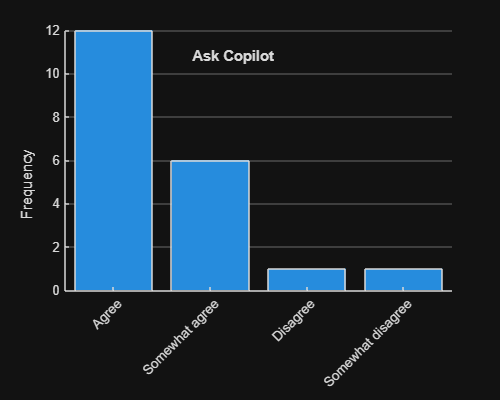

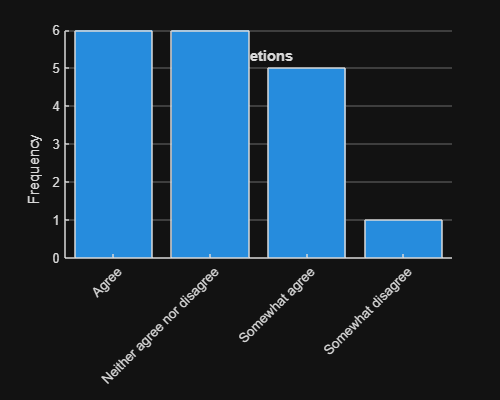

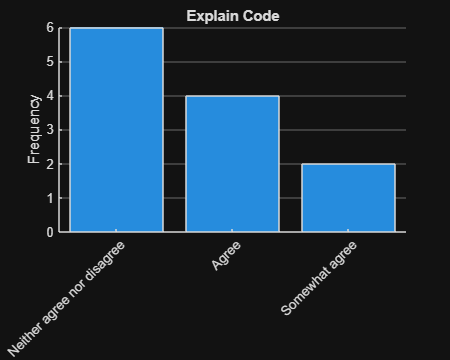

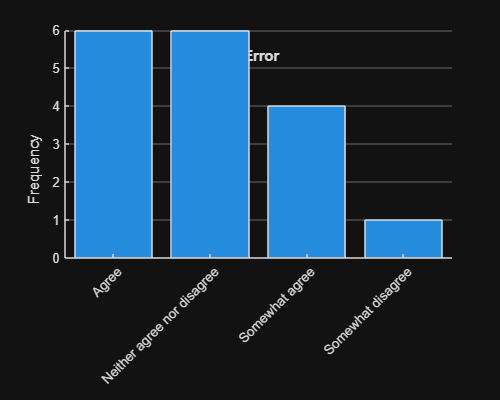

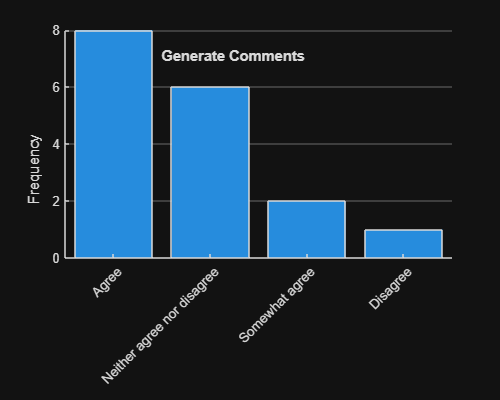

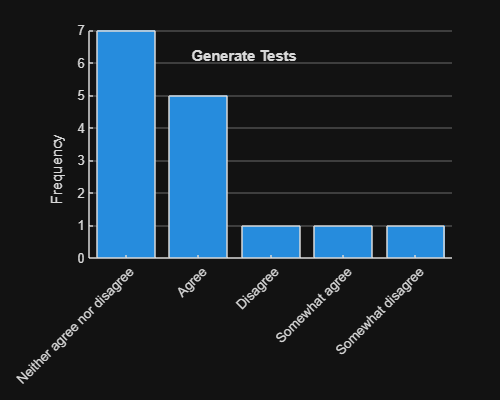

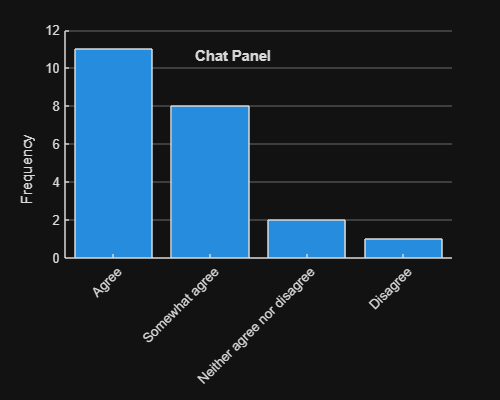

for i = 1:7
    data = data_plot(:,i);
    % Find rows that contain 'N/A'
    na_indices = strcmp(data, 'N/A');
    % Remove rows with 'N/A'
    data(na_indices) = [];

    % Create a new figure for the histogram with increased width
    figure('Position', [100, 100, 500, 400]); % Adjust the width (700) and height (400) here

    % Count the occurrences of each category
    [counts, categories] = histcounts(categorical(data), 'Normalization', 'count');
    % Plot the data using a bar chart

    % Sort categories by frequency in descending order
    [sortedCounts, sortIdx] = sort(counts, 'descend');
    sortedCategories = categories(sortIdx);

    % Plot the histogram using a bar chart for sorted categories
    bar(sortedCounts);
    % Adjust x-axis limits to fit the bars tightly
    xlim([0.5, numel(sortedCategories) + 0.5]);

    % Set x-tick labels
    xticks(1:numel(sortedCategories));
    xticklabels(sortedCategories);
    % Rotate x-tick labels for better readability if necessary
    xtickangle(45); % Adjust the angle for better readability if needed

    % Add title and labels
    title(titles{i});
    ylabel('Frequency');

    % Enable y-grid lines for better readability
    grid on;
    ax = gca; % Get current axes handle
    ax.YGrid = 'on';
    ax.XGrid = 'off'; % Optional: turn off x-grid lines
    box off
end

## Responses were accurate

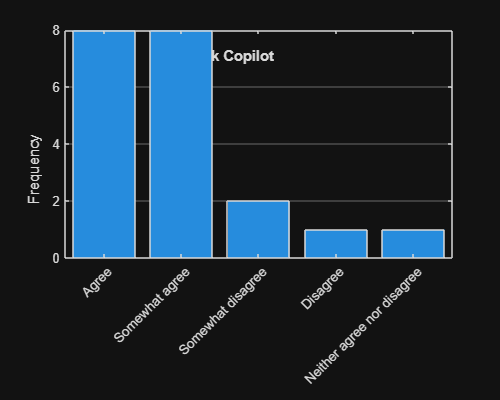

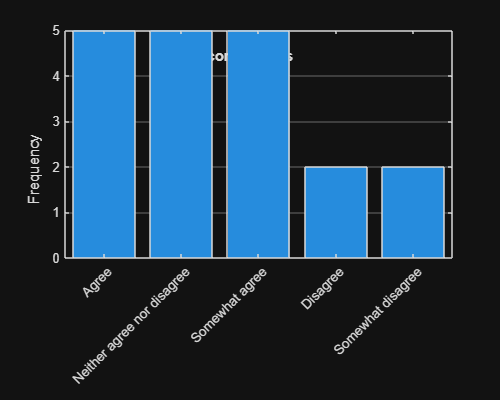

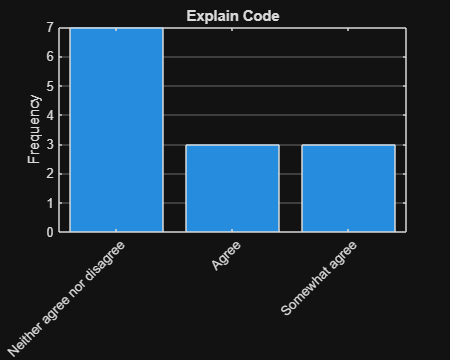

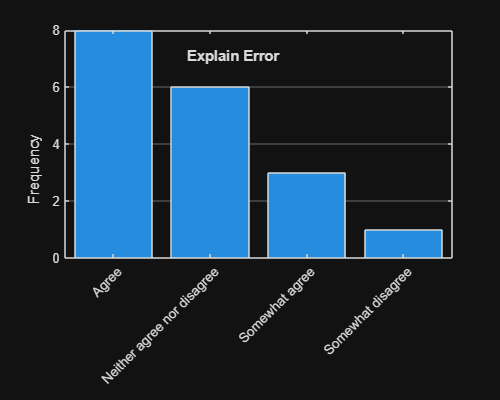

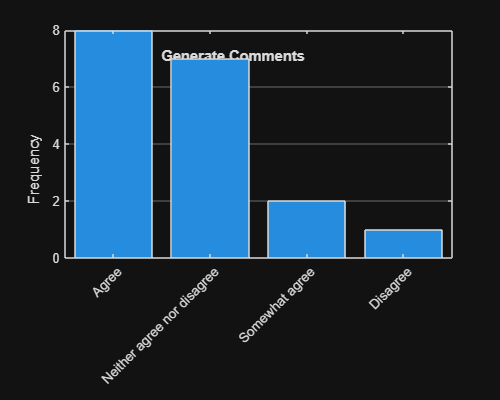

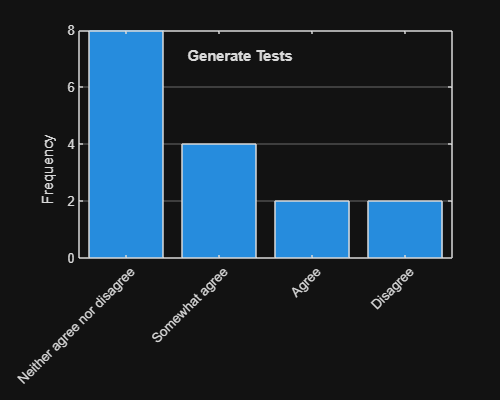

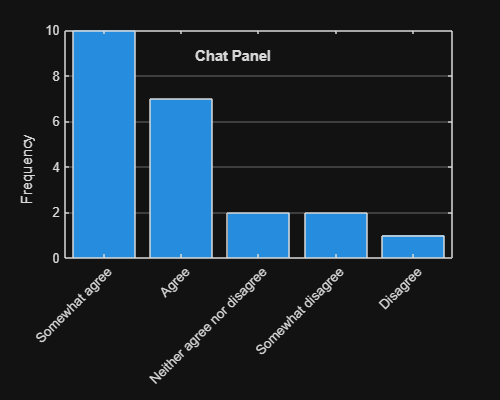

for i = 1:7
    i = i+7;
    data = data_plot(:,i);
    % Find rows that contain 'N/A'
    na_indices = strcmp(data, 'N/A');
    % Remove rows with 'N/A'
    data(na_indices) = [];

    % Create a new figure for the histogram with increased width
    figure('Position', [100, 100, 500, 400]); % Adjust the width (700) and height (400) here

    % Count the occurrences of each category
    [counts, categories] = histcounts(categorical(data), 'Normalization', 'count');
    % Plot the data using a bar chart

    % Sort categories by frequency in descending order
    [sortedCounts, sortIdx] = sort(counts, 'descend');
    sortedCategories = categories(sortIdx);

    % Plot the histogram using a bar chart for sorted categories
    bar(sortedCounts);
    % Adjust x-axis limits to fit the bars tightly
    xlim([0.5, numel(sortedCategories) + 0.5]);

    % Set x-tick labels
    xticks(1:numel(sortedCategories));
    xticklabels(sortedCategories);
    % Rotate x-tick labels for better readability if necessary
    xtickangle(45); % Adjust the angle for better readability if needed

    % Add title and labels
    title(titles{i-7});
    ylabel('Frequency');

    % Enable y-grid lines for better readability
    grid on;
    ax = gca; % Get current axes handle
    ax.YGrid = 'on';
    ax.XGrid = 'off'; % Optional: turn off x-grid lines


end

## Copilot Responses

xticksL = {'Relevant','Matched expertise','Followed MW doc','Modern standards','Easy to modify'};
% Clear conflicting variables
clear categories;

% Specify the columns of interest (24 to 28)
columnsOfInterest = 24:28;

% Extract the data from these columns
data = T(:, columnsOfInterest);

% Convert the data to a categorical array
categoricalData = varfun(@categorical, data);

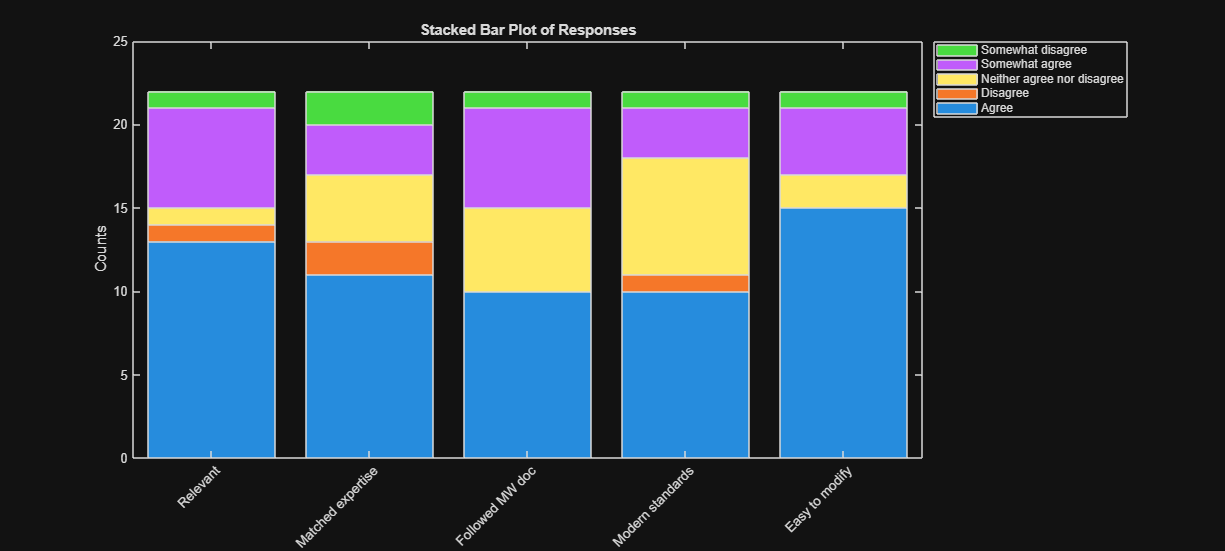


% Determine all unique categories across the selected columns
allCategories = [];

for i = 1:numel(columnsOfInterest)
    % Get unique categories for the current column
    currentCategories = categories(categoricalData{:, i});
    allCategories = union(allCategories, currentCategories);
end

% Initialize a matrix to store counts
countsMatrix = zeros(numel(allCategories), numel(columnsOfInterest));

% Count occurrences of each category in each column
for i = 1:numel(columnsOfInterest)
    % Get counts and categories for the current column
    [counts, currentCategories] = histcounts(categoricalData{:, i});

    % Map counts to the overall category list
    for j = 1:numel(currentCategories)
        categoryIndex = find(ismember(allCategories, currentCategories(j)));
        if ~isempty(categoryIndex)
            countsMatrix(categoryIndex, i) = counts(j);
        end
    end
end

% Create the stacked bar plot
figure('Position', [100, 100, 2000, 900]); % Adjust the width (700) and height (400) here
bar(countsMatrix', 'stacked');

% Add labels and title
ylabel('Counts');
title('Stacked Bar Plot of Responses');
legend(allCategories, 'Location', 'bestoutside');
xticks(1:numel(columnsOfInterest));
xticklabels(xticksL);
xlim([0.5, numel(columnsOfInterest) + 0.5]);

% Adjust the figure for better visualization
set(gca, 'XTickLabelRotation', 45);

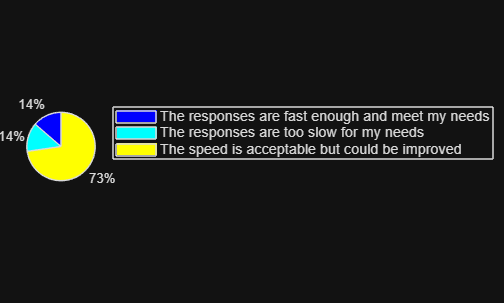

figure('Position', [100, 100, 2000, 900]); % Adjust the width (700) and height (400) here

% Extract the data from column 29
columnData = T{:, 29};

% Convert the data to a categorical array to handle unique categories
categoricalData = categorical(columnData);

% Get unique categories and their counts
[uniqueCategories, ~, categoryIndices] = unique(categoricalData);
counts = accumarray(categoryIndices, 1);

% Create the pie chart
figure;
p = pie(counts);

% Add labels to the pie chart
labels = cellstr(uniqueCategories);
legend(labels, 'Location', 'bestoutside');

% Enhance the appearance of the pie chart
colormap(jet(numel(uniqueCategories))); % Use a colormap for better colors

% Adjust the font size for better readability
set(gca, 'FontSize', 12);

## Your experience with MATLAB Copilot

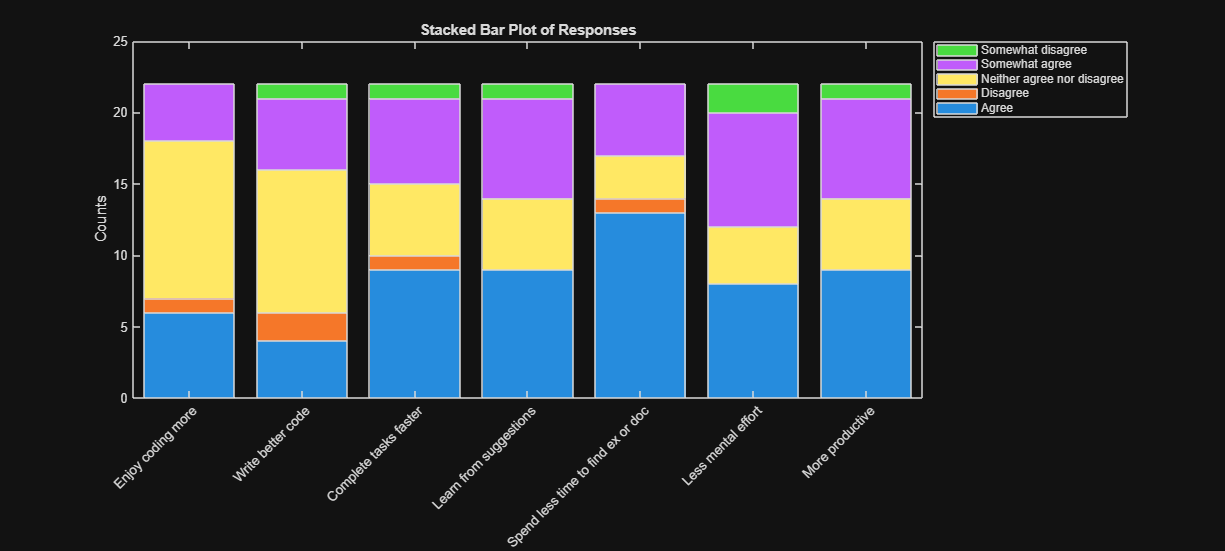

xticksL = {'Enjoy coding more','Write better code','Complete tasks faster','Learn from suggestions','Spend less time to find ex or doc','Less mental effort','More productive'};
% Clear conflicting variables
clear categories;

% Specify the columns of interest (24 to 28)
columnsOfInterest = 30:36;

% Extract the data from these columns
data = T(:, columnsOfInterest);

% Convert the data to a categorical array
categoricalData = varfun(@categorical, data);

% Determine all unique categories across the selected columns
allCategories = [];

for i = 1:numel(columnsOfInterest)
    % Get unique categories for the current column
    currentCategories = categories(categoricalData{:, i});
    allCategories = union(allCategories, currentCategories);
end

% Initialize a matrix to store counts
countsMatrix = zeros(numel(allCategories), numel(columnsOfInterest));

% Count occurrences of each category in each column
for i = 1:numel(columnsOfInterest)
    % Get counts and categories for the current column
    [counts, currentCategories] = histcounts(categoricalData{:, i});

    % Map counts to the overall category list
    for j = 1:numel(currentCategories)
        categoryIndex = find(ismember(allCategories, currentCategories(j)));
        if ~isempty(categoryIndex)
            countsMatrix(categoryIndex, i) = counts(j);
        end
    end
end

% Create the stacked bar plot
figure('Position', [100, 100, 2000, 900]); % Adjust the width (700) and height (400) here
bar(countsMatrix', 'stacked');

% Add labels and title
ylabel('Counts');
title('Stacked Bar Plot of Responses');
legend(allCategories, 'Location', 'bestoutside');
xticks(1:numel(columnsOfInterest));
xticklabels(xticksL);
xlim([0.5, numel(columnsOfInterest) + 0.5]);

% Adjust the figure for better visualization
set(gca, 'XTickLabelRotation', 45);

##  MATLAB Copilot compared to other generative AI tools

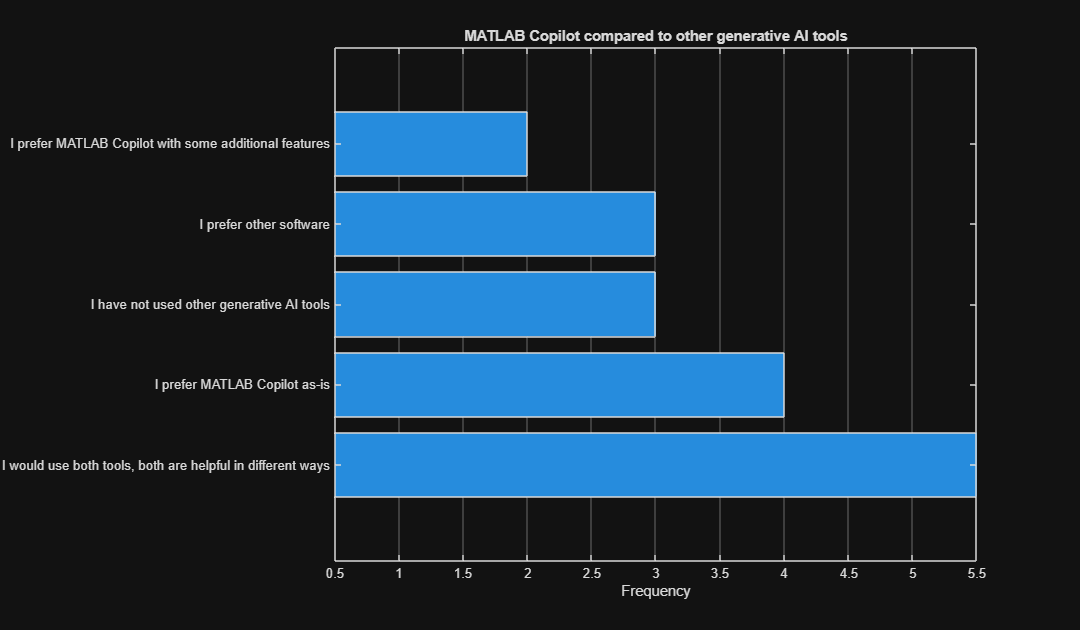

i = 39;
% Extract the data from column 29
data = T{:, i};    % Find rows that contain 'N/A'

% Create a new figure for the histogram with increased width
figure('Position', [100, 100, 1200, 700]); % Adjust the width (700) and height (400) here

% Count the occurrences of each category
[counts, categories] = histcounts(categorical(data), 'Normalization', 'count');
% Plot the data using a bar chart

% Sort categories by frequency in descending order
[sortedCounts, sortIdx] = sort(counts, 'descend');
sortedCategories = categories(sortIdx);

% Plot the histogram using a bar chart for sorted categories
barh(sortedCounts);
% Adjust x-axis limits to fit the bars tightly
xlim([0.5, numel(sortedCategories) + 0.5]);

% Set x-tick labels
yticks(1:numel(sortedCategories));
yticklabels(sortedCategories);
% Rotate x-tick labels for better readability if necessary
% ytickangle(45); % Adjust the angle for better readability if needed

% Add title and labels
title('MATLAB Copilot compared to other generative AI tools');
xlabel('Frequency');

% Enable y-grid lines for better readability
grid on;
ax = gca; % Get current axes handle
ax.XGrid = 'on';
ax.YGrid = 'off'; % Optional: turn off x-grid lines